# Read Spectrometer Dataset Example

Copyright 2022-2023 Battelle Memorial Institute

This example shows how to use function `pnnl_read_spectrometer_dataset` to load spectrometer datasets from multiple files.  The spectrometer data is organized in the following way.

- All files from a single dataset are in one directory.

- The data in each file are row oriented.

- Each file contains one spectrum.

- The first row in each file is the "x" data (Wavenumbers).

- All wavenumbers are the same for all of the files in a directory.

- The second row in each file is the "y" data (Absorbance spectrum).

Function `pnnl_read_spectrometer_dataset` has the following syntax that you can see by using the help command on the function (as you can with any MATLAB function).

help pnnl_read_spectrometer_dataset

  pnnl_read_spectrometer_dataset Read spectrometer dataset
 
    [AbsorbanceMatrix, Wavenumbers] = ...
        pnnl_read_spectrometer_dataset(directory_name, file_extension)
 
    reads all files in a directory specified by directory_name with
    file extension specified by file_extension.
 
    If no directory name is specified, or if the directory name is an
    empty string, then the files are read from the current directory.
 
    If no file extension is specified, or if file extension is an empty
    string, then a file extension of 'txt' is used.
 
    [AbsorbanceMatrix, Wavenumbers] = pnnl_read_spectrometer_dataset
    with no additional input arguments reads all files in the current
    directory with file extension 'txt'.
 
    Files whose names start with '._' are ignored.  They are assumed to
    be file attributes created by Mac computers.
 
    Example:
 
      training_data_directory_name = ...
          fullfile('pnnl_s

The files in this example are the spectrometer dataset files that were used to create `A_train`, `A_unknown`, and `Wavenumbers` that are used in the rest of PNNL Chemometric Toolbox, and are identical to the data you get when you load `pnnl_napalm_data.mat` in the MATLAB Workspace.

If your data is in a different format, then you can copy `pnnl_read_spectrometer_dataset.m `and modify it for your own purposes.

Clear variables from the workspace before beginning the example.

clearvars

## Specify Directories Containing Training and Unknown Dataset files

All training data is in one directory and all unknown data is in another directory.  All of the files in each directory are assumed to be in the same dataset.

Change the locations of the directories to where your own data is stored.

Both datasets are contained in a directory named `pnnl_spectrometer_data` that is a sub-directory of the `pnnl_chemometric_toolbox` directory.

The training dataset is contained in a sub-directory of `pnnl_spectrometer_data` named `pnnl_napalm_training_dataset`.

Use `fullfile` to specify a path to a directory with a subdirectory so the path names work on Windows, Linux, and Mac.  If you are in the directory that contains the dataset files, then let the directory name be an empty string `''`.

training_data_directory = fullfile('pnnl_spectrometer_data','pnnl_napalm_training_dataset')

training_data_directory = 'pnnl_spectrometer_data/pnnl_napalm_training_dataset'

The training data directory has 20 text files containing one spectrum in each file.

dir(training_data_directory)

.                xy_train_04.txt  xy_train_09.txt  xy_train_14.txt  xy_train_19.txt  
..               xy_train_05.txt  xy_train_10.txt  xy_train_15.txt  xy_train_20.txt  
xy_train_01.txt  xy_train_06.txt  xy_train_11.txt  xy_train_16.txt  
xy_train_02.txt  xy_train_07.txt  xy_train_12.txt  xy_train_17.txt  
xy_train_03.txt  xy_train_08.txt  xy_train_13.txt  xy_train_18.txt  



The unknown dataset is contained in a sub-directory of `pnnl_spectrometer_data` named `pnnl_napalm_unknown_dataset`.

unknown_data_directory = fullfile('pnnl_spectrometer_data','pnnl_napalm_unknown_dataset')

unknown_data_directory = 'pnnl_spectrometer_data/pnnl_napalm_unknown_dataset'

The unknown directory has 12 text files containing one spectrum in each file.

dir(unknown_data_directory)

.                  xy_unknown_02.txt  xy_unknown_05.txt  xy_unknown_08.txt  xy_unknown_11.txt  
..                 xy_unknown_03.txt  xy_unknown_06.txt  xy_unknown_09.txt  xy_unknown_12.txt  
xy_unknown_01.txt  xy_unknown_04.txt  xy_unknown_07.txt  xy_unknown_10.txt  



## Specify the File Extension

All of the files in the dataset were saved with a "txt" extension by the spectrometer.

file_extension = 'txt';

## Load the Datasets

Read the spectrometer dataset for the training data.  The absorbance data is the first output.  The wavenumber vector is the second output.

[A_train, Wavenumbers] = pnnl_read_spectrometer_dataset(training_data_directory, file_extension);

Read the spectrometer dataset for the unknown data.  The absorbance data is the first outout.  The wavenumbers are the same for the unknown data and the training data, so you don't need to use the second output in this case.

A_unknown = pnnl_read_spectrometer_dataset(unknown_data_directory, file_extension);

## Examine the Data

List all the variables in the workspace.

whos

  Name                          Size               Bytes  Class     Attributes

  A_train                      20x1713            274080  double              
  A_unknown                    12x1713            164448  double              
  Wavenumbers                   1x1713             13704  double              
  file_extension                1x3                    6  char                
  training_data_directory       1x51                 102  char                
  unknown_data_directory        1x50                 100  char                



Plot the training spectra.

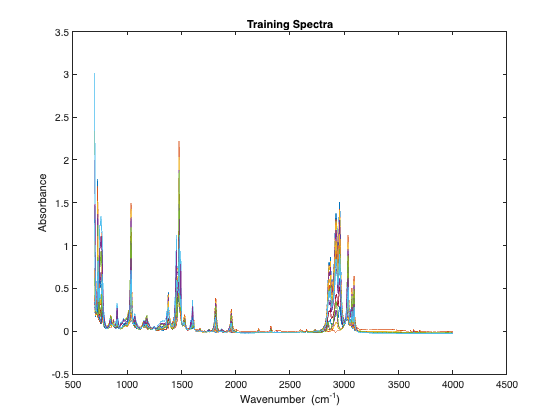

plot(Wavenumbers,A_train)
xlabel('Wavenumber (cm^{-1})')
ylabel('Absorbance')
title('Training Spectra')

Plot the unkown spectra.

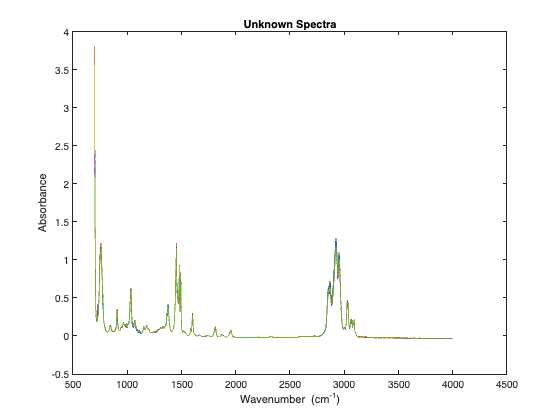

plot(Wavenumbers,A_unknown)
xlabel('Wavenumber (cm^{-1})')
ylabel('Absorbance')
title('Unknown Spectra')

# Disclaimer

This material was prepared as an account of work sponsored by an agency of the United States Government. Neither the United States Government nor the United States Department of Energy, nor Battelle, nor any of their employees, nor any jurisdiction or organization that has cooperated in the development of these materials, makes any warranty, express or implied, or assumes any legal liability or responsibility for the accuracy, completeness, or usefulness or any information, apparatus, product, software, or process disclosed, or represents that its use would not infringe privately owned rights.

Reference herein to any specific commercial product, process, or service by trade name, trademark, manufacturer, or otherwise does not necessarily constitute or imply its endorsement, recommendation, or favoring by the United States Government or any agency thereof, or Battelle Memorial Institute. The views and opinions of authors expressed herein do not necessarily state or reflect those of the United States Government or any agency thereof.

PACIFIC NORTHWEST NATIONAL LABORATORY

operated by

BATTELLE

for the

UNITED STATES DEPARTMENT OF ENERGY

under Contract DE-AC05-76RL01830